# Hyperparamters search

## Load training and testing data

% Current script is currently design to work with two different datasets:
% (a) https://openneuro.org/datasets/ds002778/versions/1.0.4
% 15 individuals with Parkinsons disease, and 16 controls recorded at Resting State
% 16 healthy and 15 patients with Parkinson's recorded at Resting State
% (b) https://openneuro.org/datasets/ds004584
% 100 individuals with Parkinsons disease, and 49 controls

addpath("Utils");
addpath("Models");

splitting = false;
dataset_name = "ds002778";

if(dataset_name == "ds002778")
    stepLength = 64;
elseif(dataset_name == "ds004584")
    stepLength = 125;
else
    error("Not known dataset");
end

folderNameLoadFrom = fullfile('Data',dataset_name + '_prepared','HyperparameterSearch');
folderNameToSaveTo = fullfile('Results',dataset_name,'HyperparameterSearch');

if(~exist(folderNameToSaveTo, 'dir'))
    mkdir(folderNameToSaveTo);
end

if(splitting)
    load(fullfile(folderNameLoadFrom,'Train','XSearchTrainNoSplitting.mat'));
    load(fullfile(folderNameLoadFrom,'Train','YSearchTrainNoSplitting.mat'));
    load(fullfile(folderNameLoadFrom,'Test','XSearchTestNoSplitting.mat'));
    load(fullfile(folderNameLoadFrom,'Test','YSearchTestNoSplitting.mat'));
else
    load(fullfile(folderNameLoadFrom,'Train','XSearchTrain.mat'));
    load(fullfile(folderNameLoadFrom,'Train','YSearchTrain.mat'));
    load(fullfile(folderNameLoadFrom,'Test','XSearchTest.mat'));
    load(fullfile(folderNameLoadFrom,'Test','YSearchTest.mat'));
end


% We experiment with 1,3, and 5 frontal electrodes. 
numChannels = 5; % Selected number of electrodes

selectChannels = @(cellArray, channels) cellfun(@(x) x(channels,:), cellArray, 'UniformOutput', false);

if(splitting) % The records are split in smaller and overlapping segments
    sequenceLenghts = @(dataset) cellfun(@(x) size(x,2), dataset);
    [~, idx] = sort(sequenceLenghts(XSearchTrainNoSplitting));
    XSearchTrainPrepared = selectChannels(XSearchTrainNoSplitting(idx), 1:numChannels);
    YSearchTrainPrepared = YSearchTrainNoSplitting(idx);
    
    [~, idx] = sort(sequenceLenghts(XSearchTestNoSplitting));
    XSearchTestPrepared = selectChannels(XSearchTestNoSplitting(idx), 1:numChannels);
    YSearchTestPrepared = YSearchTestNoSplitting(idx);
else % The records are not split into smaller segmets 
    XSearchTrainPrepared = selectChannels(XSearchTrain, 1:numChannels);
    YSearchTrainPrepared = YSearchTrain;
    
    XSearchTestPrepared = selectChannels(XSearchTest, 1:numChannels);
    YSearchTestPrepared = YSearchTest;
end

## Set the training parameters

MaxEpochs = 100;
scheduler = cosineLearnRate(InitialFactor   = 1, ....
                           FinalFactor      = 0.05, ...
                           Period           = MaxEpochs, ...
                           FrequencyUnit    ="epoch");

%scheduler = cyclicalLearnRate(MaxFactor=10,FrequencyUnit="epoch", Period=20, StepRatio=0.2);

options = trainingOptions('adam', ...
    LearnRateSchedule   = scheduler, ...
    InitialLearnRate    = 1,...
    SequenceLength      = 'shortest', ...
    ExecutionEnvironment= 'gpu',...
    ValidationPatience  = 10,...
    L2Regularization    = .001,...
    OutputNetwork       = 'last-iteration',...
    ValidationData      = {XSearchTestPrepared,  YSearchTestPrepared}, ...
    MiniBatchSize       = ceil(size(XSearchTrainPrepared,2)/15),...
    ValidationFrequency = 50,...
    Verbose             = false,...
    MaxEpochs           = MaxEpochs,...
    Shuffle             = "every-epoch",...
    Plots               = "none");

if(splitting)
    options.MiniBatchSize       = 1;
    options.MaxEpochs           = MaxEpochs;
    options.LearnRateDropPeriod = 20;
end

numTrials = 3;
rng(1);

## (1) 4 Models: Search for best parameters for LSTM/GRU/BiLSTM/BiGRU

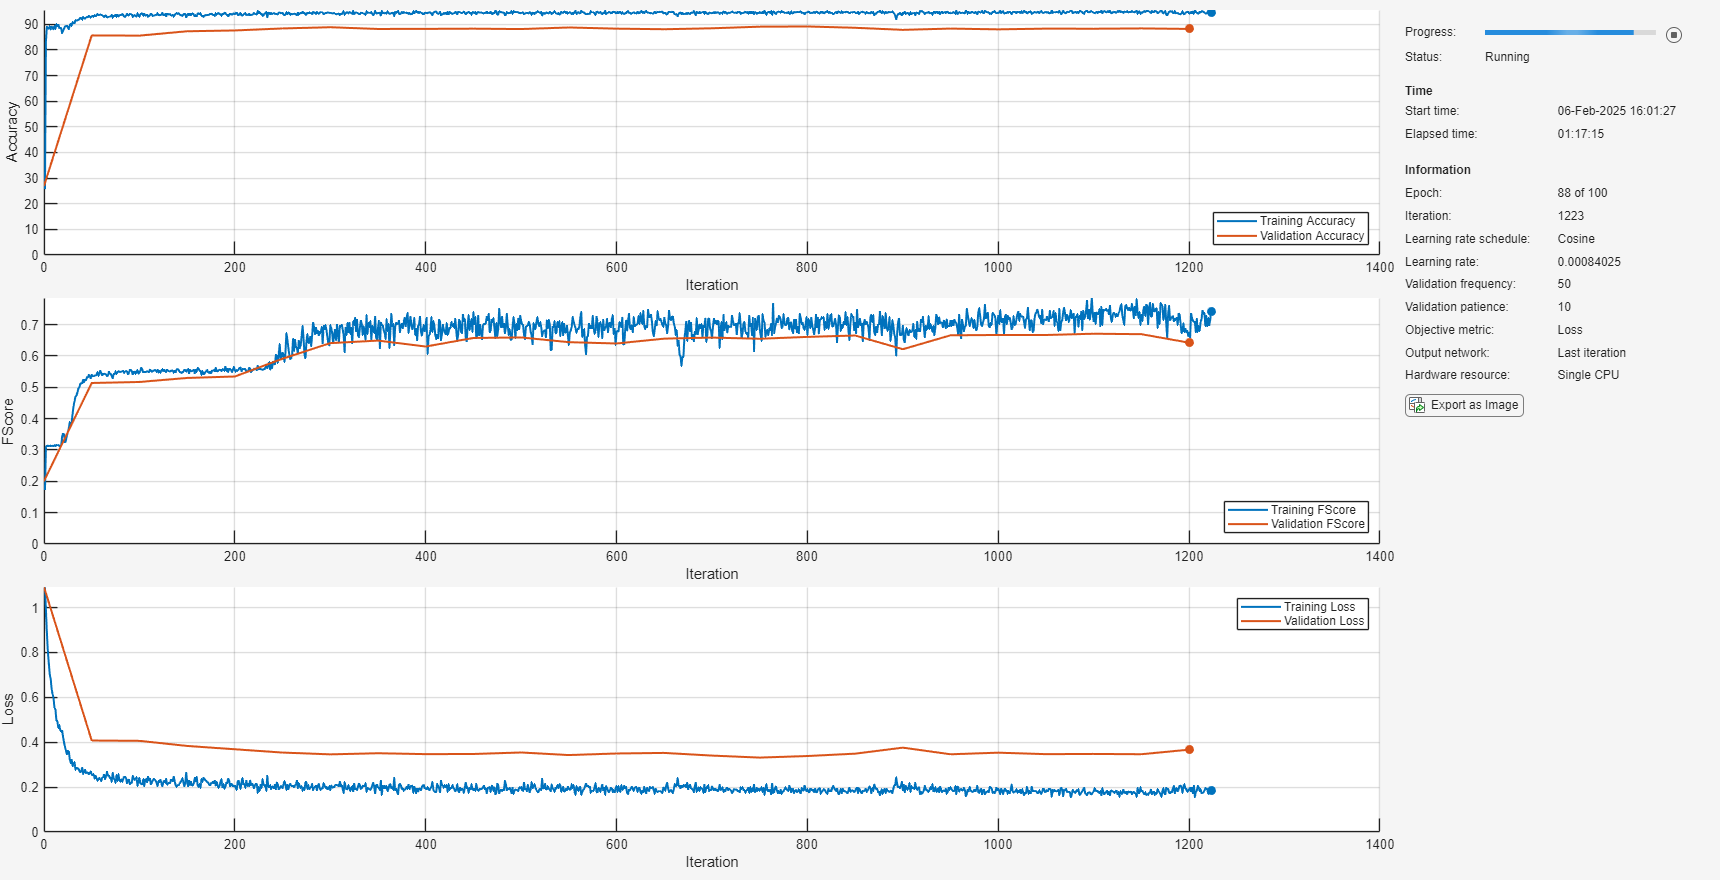

commonHParameters = struct(...
    'numLabels',        3,...           % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'numUnits',         2.^(3:5),...
    'numRBlocks',       1:4,...
    'typeOfUnit',       ["bigruLayerGraph", "bilstmLayer", "gruLayer", "lstmLayer"]); % "bigruLayer", 

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "cpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"]; % , "recall", "precision"
rnnResults = gridSearch(@constructRNN, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID,...
                                        XSearchTestPrepared, YSearchTestPrepared, XSearchTestID, ...
                                        commonHParameters, options, numTrials, stepLength,...
                                        ["numRBlocks", "numUnits", "typeOfUnit"]);

save(fullfile(folderNameToSaveTo, "rnnResults_" + numChannels + ".mat"), "rnnResults");

## (2) 1 Model: Search for best parameters for TCN(depth-wise)

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       [5, 11, 15],...
    'numFilters',       2.^(3:5),...
    'numBlocks',        1:4);

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"]; % , "recall", "precision"
tcnResults = gridSearch(@constructTCN, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                       XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                       commonHParameters, options, numTrials, stepLength,...
                                        ["numBlocks", "numFilters", "filterSize"]);

save(fullfile(folderNameToSaveTo, "tcnResults_" + numChannels + ".mat"), 'tcnResults');

## (3) 1 Model: Search for best parameters for TCN(standard)

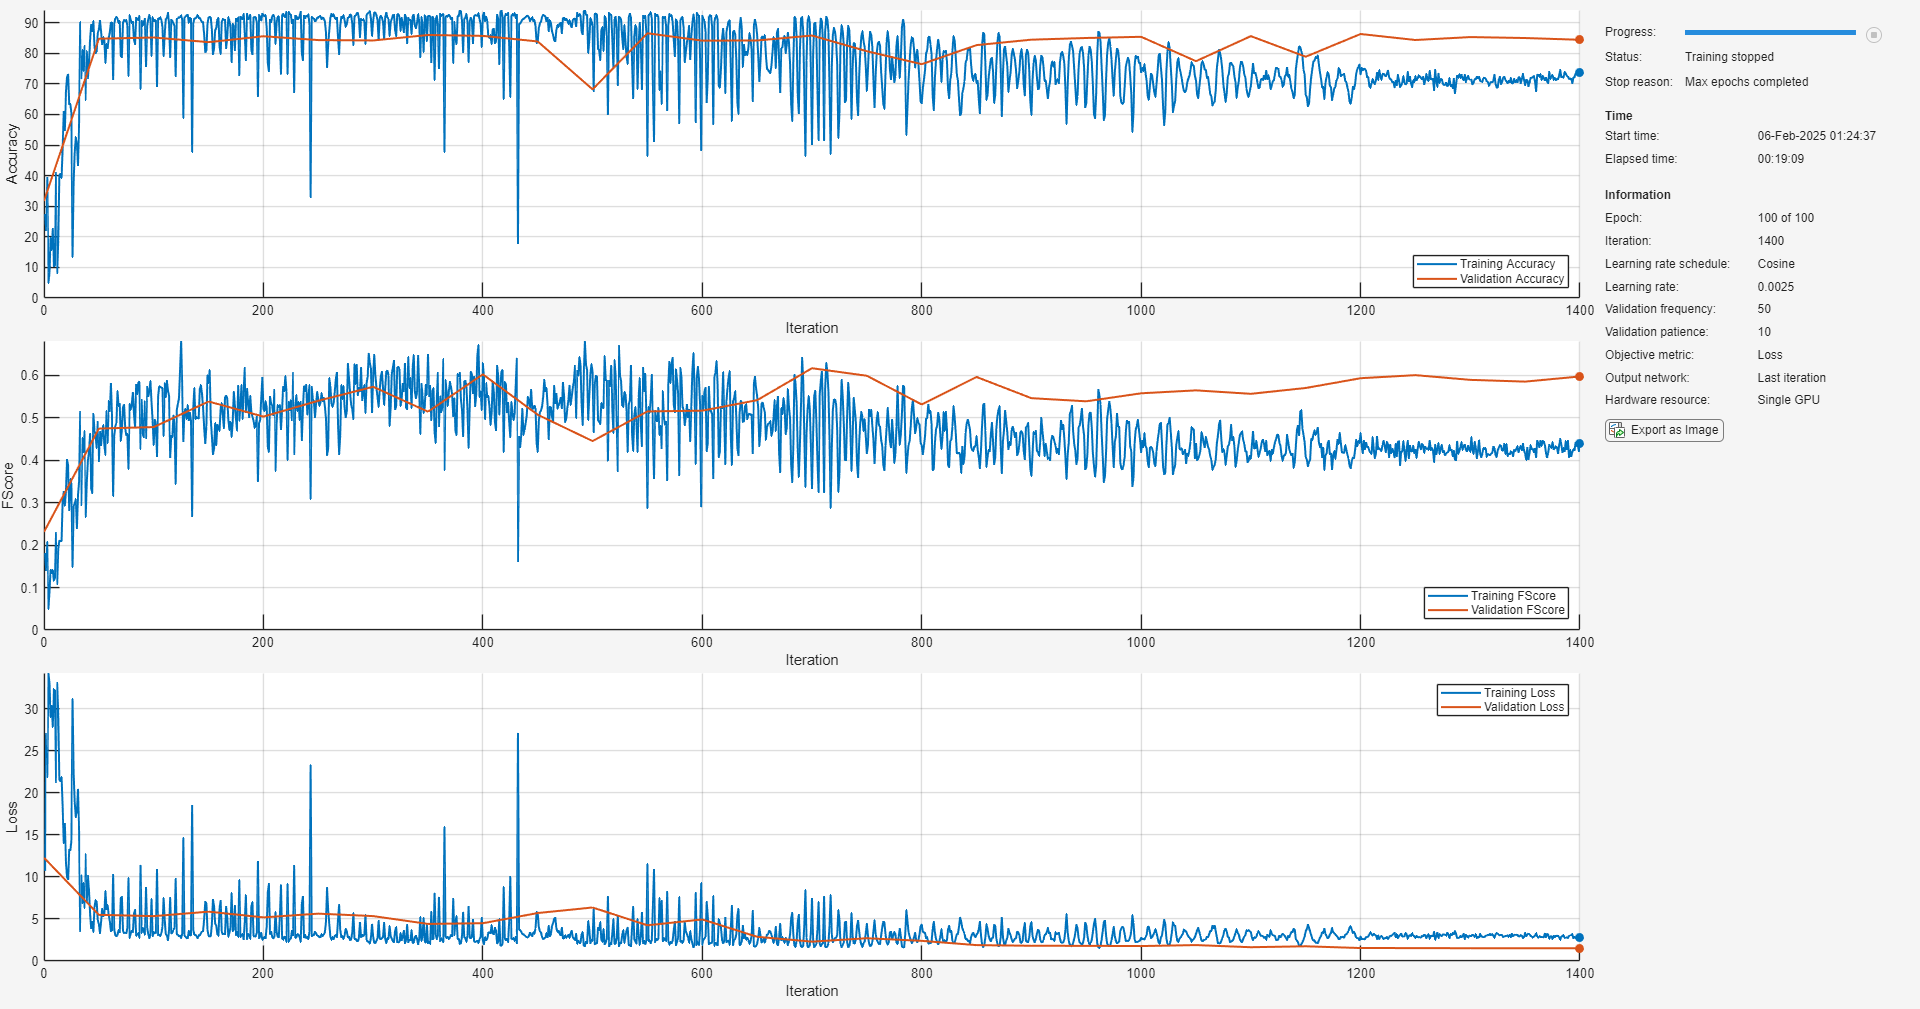

commonHParameters = struct(...

    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       [5, 11, 15],...
    'numFilters',       2.^(3:5),...
    'numBlocks',        1:4);


% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
tcnStandardResults = gridSearch(@constructTCNs, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                       XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                       commonHParameters, options, numTrials, stepLength,...
                                        ["numBlocks", "numFilters", "filterSize"]);
save(fullfile(folderNameToSaveTo, "tcnStandardResults_" + numChannels + ".mat"), 'tcnStandardResults');

## (4) 1 Model: Search for best parameters for CNN (depth-wise)

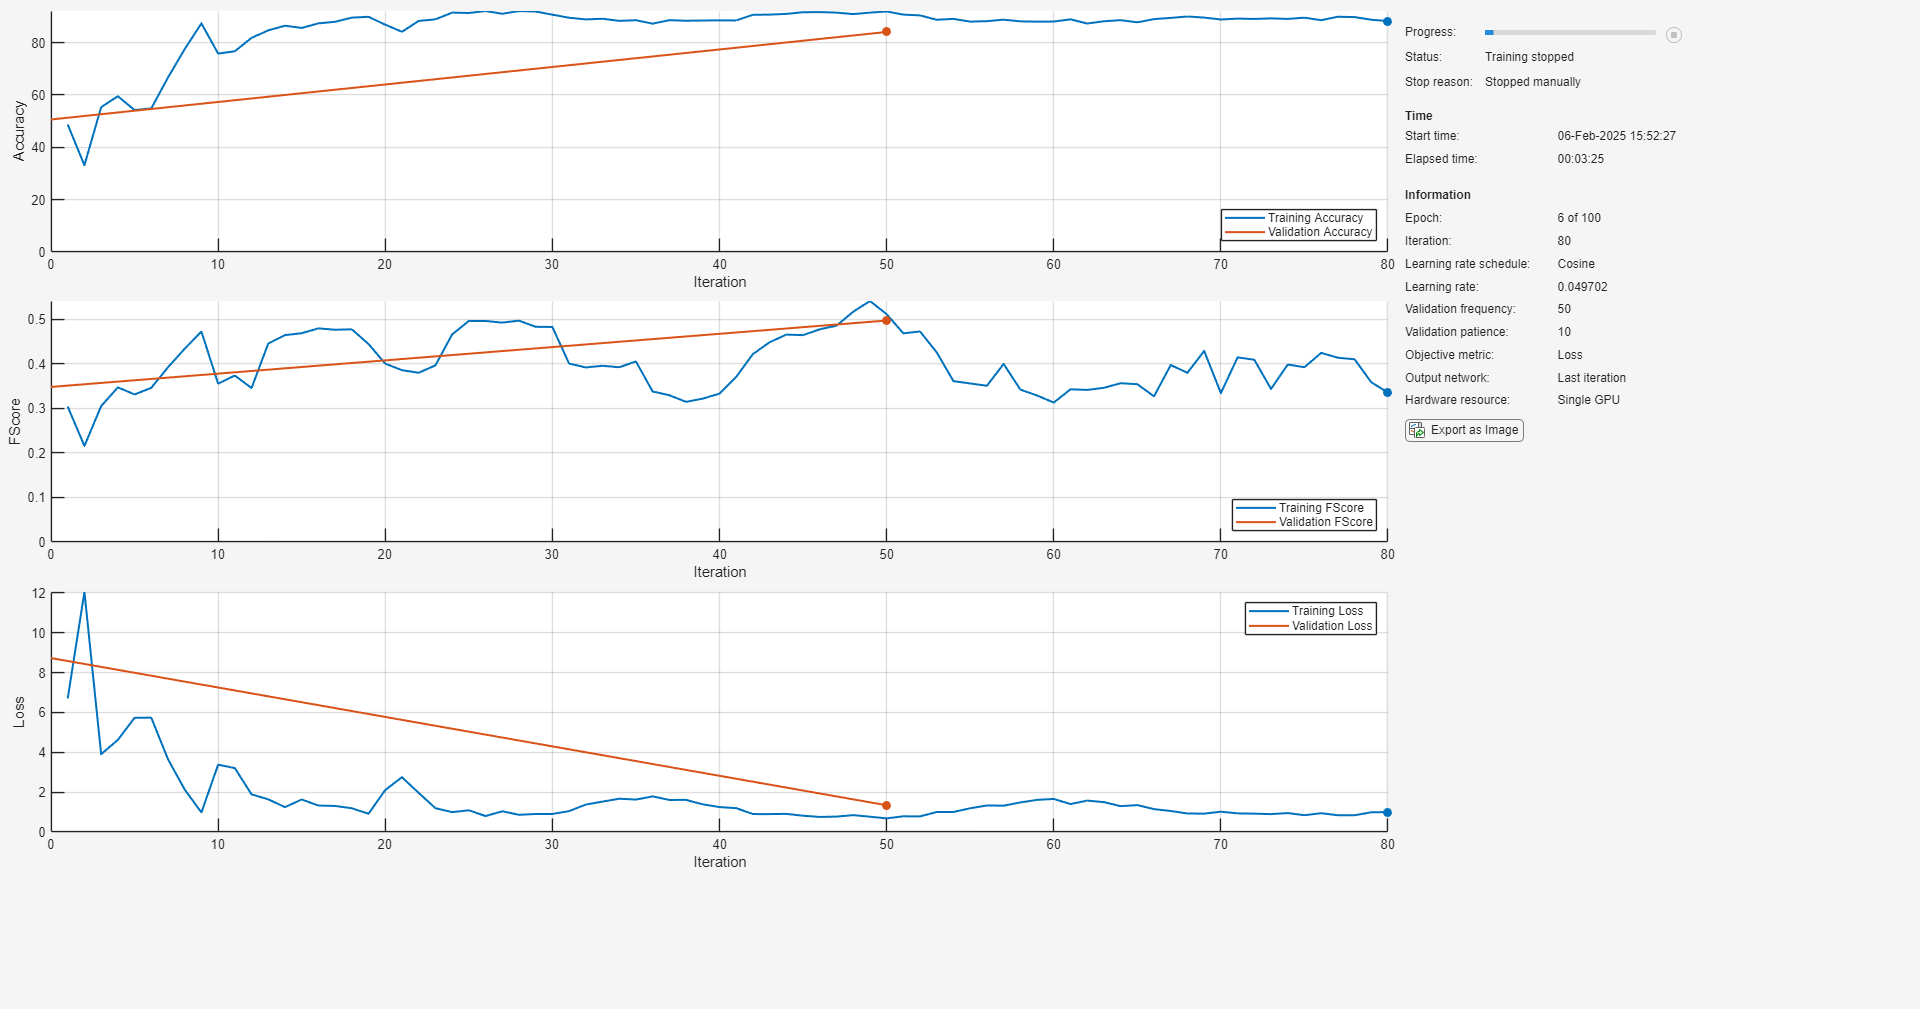

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]

    'dropoutFactor',    0.125,...
    'filterSize',       [5, 11, 15],...
    'numFilters',       2.^(3:5),...
    'numBlocks',        1:4);

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
cnnDWResults = gridSearch(@constructCNN, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                       XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                       commonHParameters, options, numTrials, stepLength,...
                                        ["numBlocks", "numFilters", "filterSize"]);

save(fullfile(folderNameToSaveTo, "cnnDWResults_" + numChannels + ".mat"), 'cnnDWResults');

## (5) 1 Model: Search for best parameters for CNN (standard)

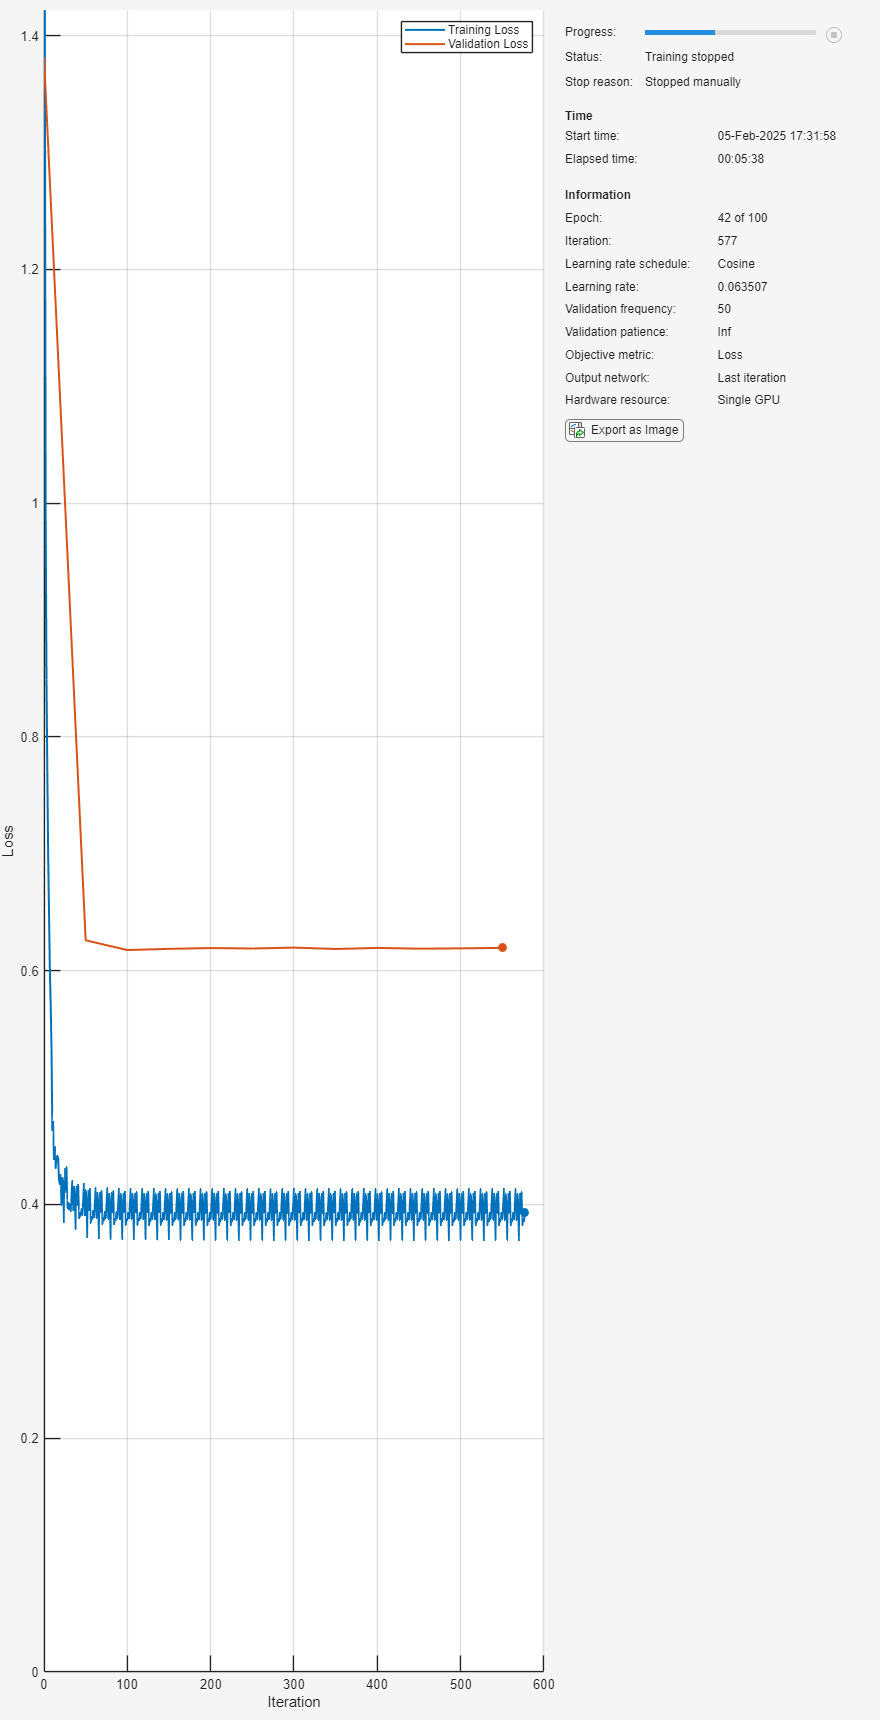

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]

    'dropoutFactor',    0.125,...
    'filterSize',       [5, 11, 15],...
    'numFilters',       2.^(3:5),...
    'numBlocks',        1:4);

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
cnnSResults = gridSearch(@constructCNNs, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                       XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                       commonHParameters, options, numTrials, stepLength,...
                                        ["numBlocks", "numFilters", "filterSize"]);
save(fullfile(folderNameToSaveTo, "cnnSResults_" + numChannels + ".mat"), 'cnnSResults');

## (6) 2 Models: Search for best parameters for CNNRNN (depth-wise)

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       15,...
    'numFilters',       32,...
    'numBlocks',        1:3,...
    'numUnits',         2.^(3:5),...
    'numRBlocks',       1:2,...
    'typeOfUnit',       ["bigruLayerGraph","bilstmLayer"]); % bigruLayer

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
cnnDWrnnResults = gridSearch(@constructCNNRNN,  XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                              XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                              commonHParameters, options, numTrials, stepLength,...
                                              ["typeOfUnit", "numUnits", "numBlocks", "numRBlocks"]);
save(fullfile(folderNameToSaveTo, "cnnDWrnnResults_" + numChannels + ".mat"), 'cnnDWrnnResults');

## (7) 2 Models: Search for best parameters for CNNRNN (standard)

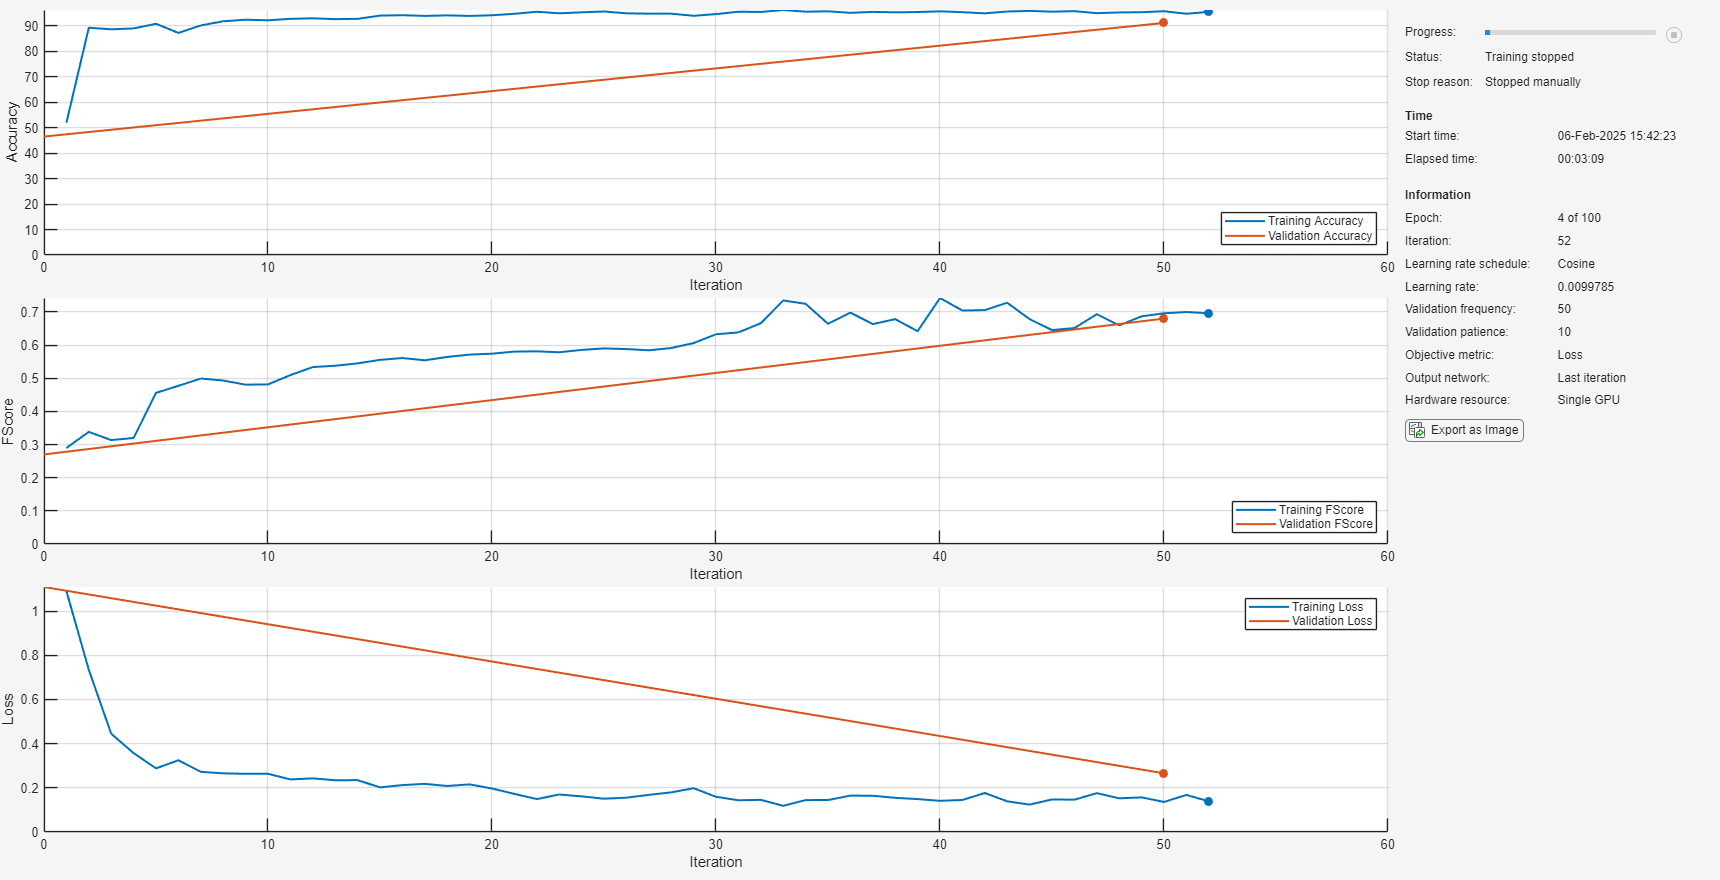

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       15,...
    'numFilters',       32,...

    'numBlocks',        1:3,...
    'numUnits',         2.^(3:5),...
    'numRBlocks',       1:2,...
    'typeOfUnit',       ["bigruLayerGraph", "bilstmLayer"]); % bigruLayer

% numTrials = 1;
% options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
cnnSrnnResults = gridSearch(@constructCNNRNNs,  XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                       XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                       commonHParameters, options, numTrials, stepLength,...
                                        ["typeOfUnit", "numUnits", "numBlocks", "numRBlocks"]);
save(fullfile(folderNameToSaveTo, "cnnSrnnResults_" + numChannels + ".mat"), 'cnnSrnnResults');

## (8) 2 Model: Search for best parameters for TCNRNN (standard)

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       15,...
    'numFilters',       32,...
    'numBlocks',        1:3,...     % TCN blocks
    'numUnits',         2.^(3:5),...% RNN units
    'numRBlocks',       1:2,...     % RNN blocks
    'typeOfUnit',       ["bigruLayerGraph","bilstmLayer"]); % bigruLayer

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
tcnSrnnResults = gridSearch(@constructTCNsRNN,  XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                              XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                              commonHParameters, options, numTrials, stepLength,...
                                              ["typeOfUnit", "numUnits", "numBlocks", "numRBlocks"]);
save(fullfile(folderNameToSaveTo, "tcnSrnnResults_" + numChannels + ".mat"), 'tcnSrnnResults');


## (9) 2 Model: Search for best parameters for TCNRNN (depth-wise)

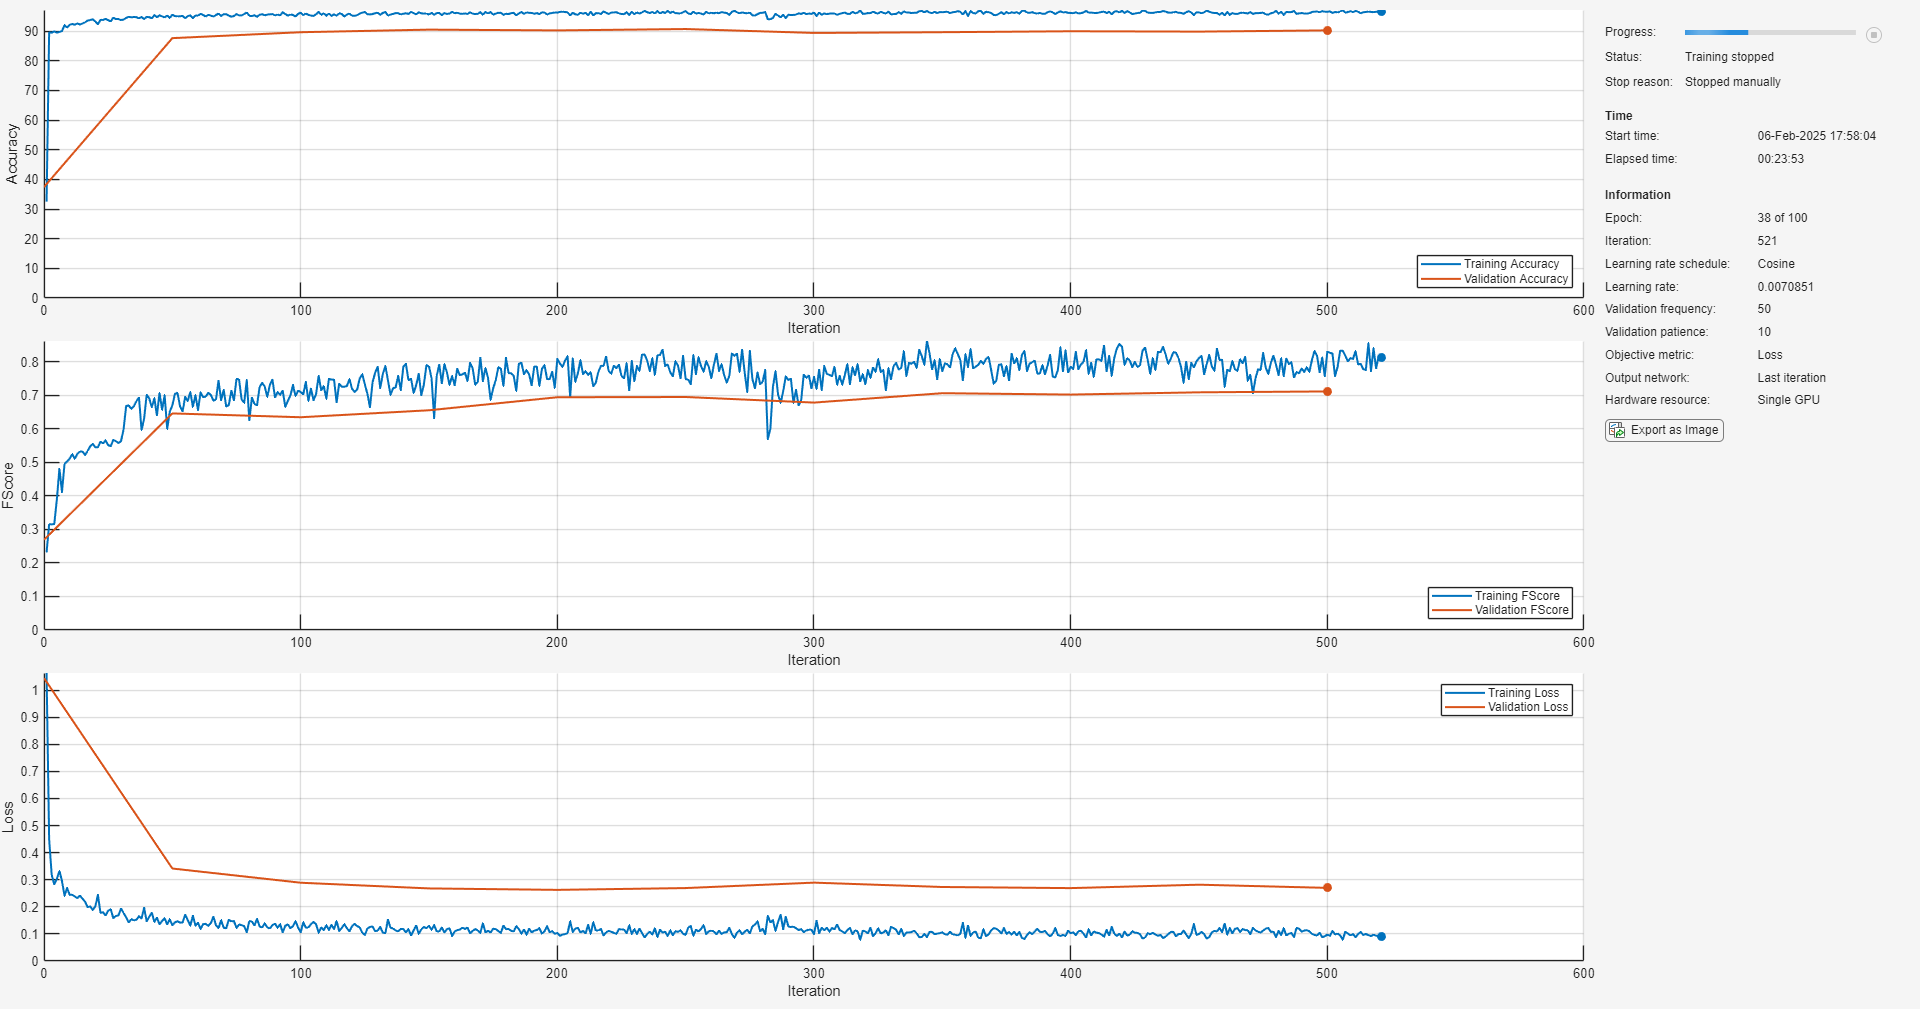

commonHParameters = struct(...
    'numLabels',        3,... % i.e. {'blink', 'n/a', 'muscle-artifact'}
    'numChannels',      numChannels,... % Channels are stored in the followign order ["Fp1", "Fp2", "Fz", "AF3", "AF4"]
    'dropoutFactor',    0.125,...
    'filterSize',       15,...
    'numFilters',       32,...
    'numBlocks',        1:3,...     % TCN blocks

    'numUnits',         2.^(3:5),...% RNN units
    'numRBlocks',       1:2,...     % RNN blocks
    'typeOfUnit',       ["bigruLayerGraph","bilstmLayer"]); % bigruLayer

% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
tcnDWrnnResults = gridSearch(@constructTCNRNN,  XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                              XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID,...
                                              commonHParameters, options, numTrials, stepLength,...
                                              ["typeOfUnit", "numUnits", "numBlocks", "numRBlocks"]);
save(fullfile(folderNameToSaveTo, "tcnDWrnnResults_" + numChannels + ".mat"), 'tcnDWrnnResults');

## (10) 1 Model: Search for best parameters for Transformer-based models

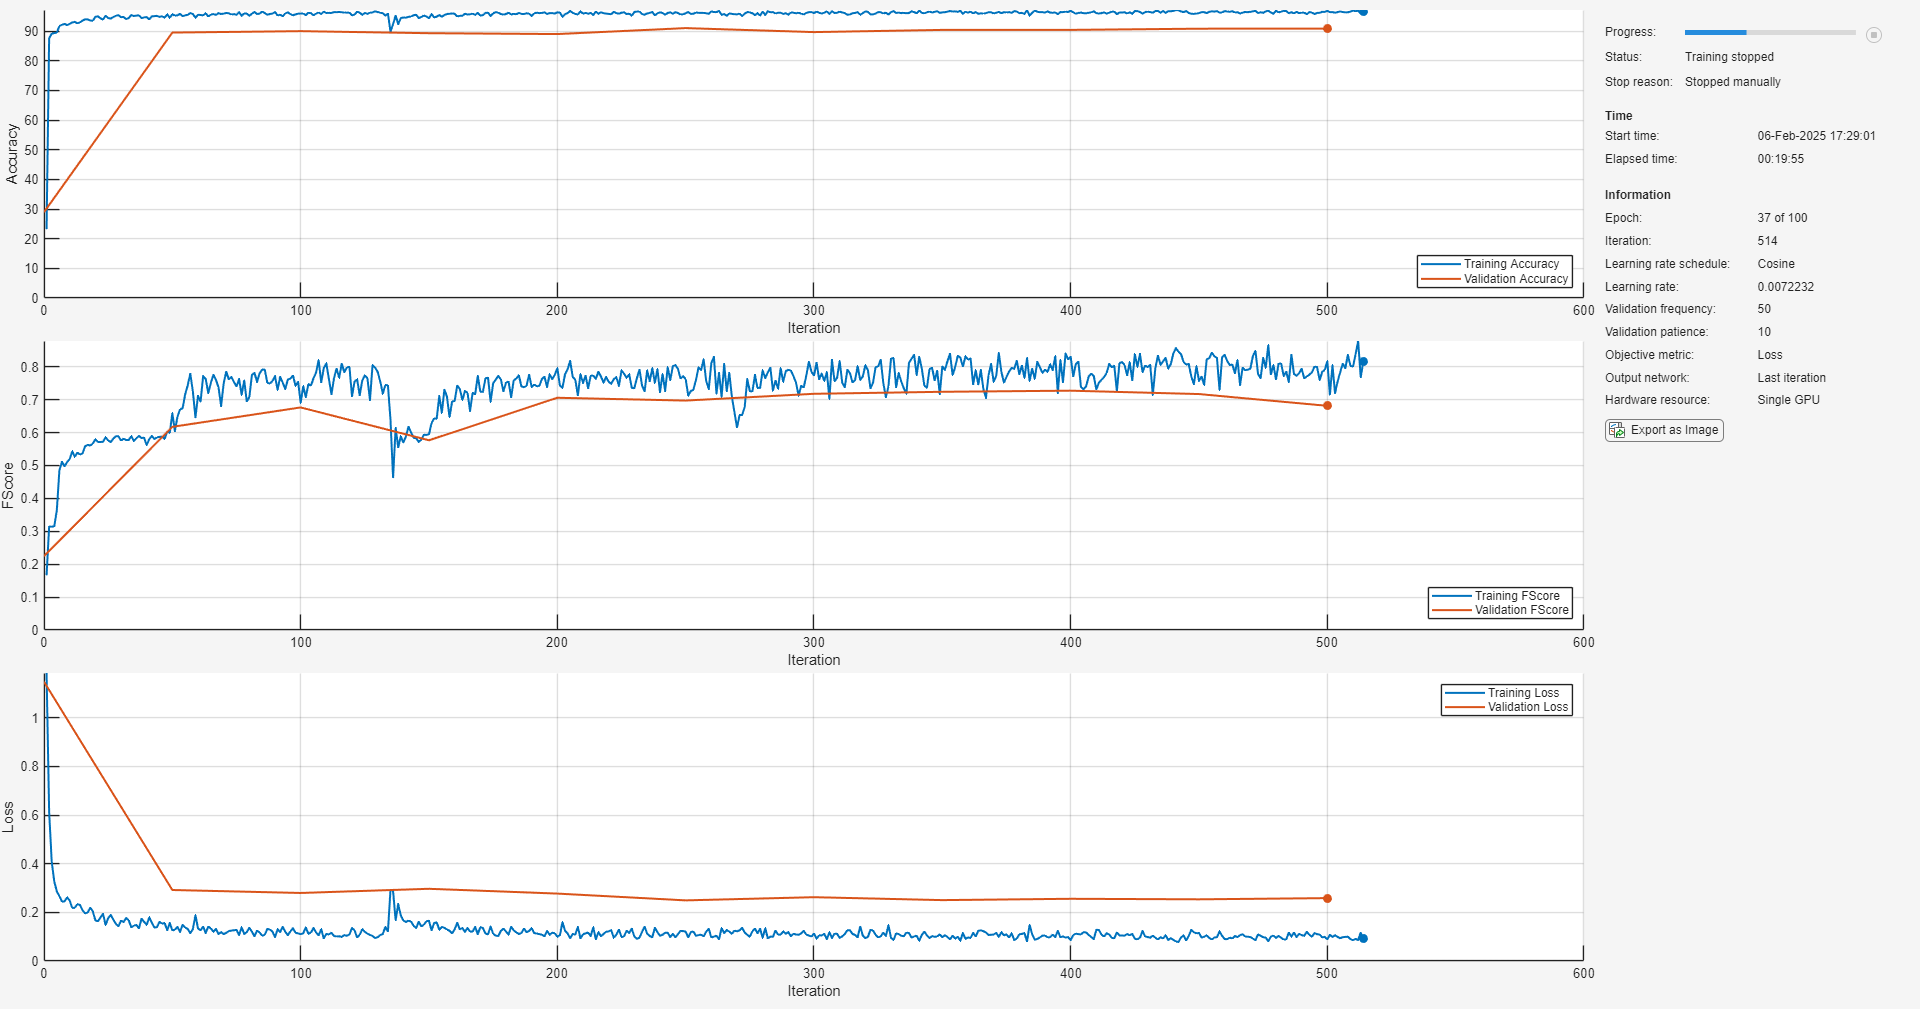

%% Grid Search for Transformer Model
commonHParameters = struct(...
    'numLabels', 3,...
    'numChannels', numChannels,...
    'dropoutFactor', 0.125,  ...
    'embedDim', [32 64],...
    'numHeads', [2 4], ...          % Number of attention heads
    'numTransformerBlocks', [1 2] ...          % Number of transformer blocks
);


% Run grid search
% numTrials = 1;
% options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
transformerResults = gridSearch(@constructTransformer, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                              XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID, ...
                                              commonHParameters, options, numTrials, stepLength, ...
                                             ["embedDim", "numHeads", "numTransformerBlocks"]);

save(fullfile(folderNameToSaveTo, "transformerResults_" + numChannels + ".mat"), 'transformerResults');

## (11) 1 Model: Search for best parameters for Transformer-DWCNN models

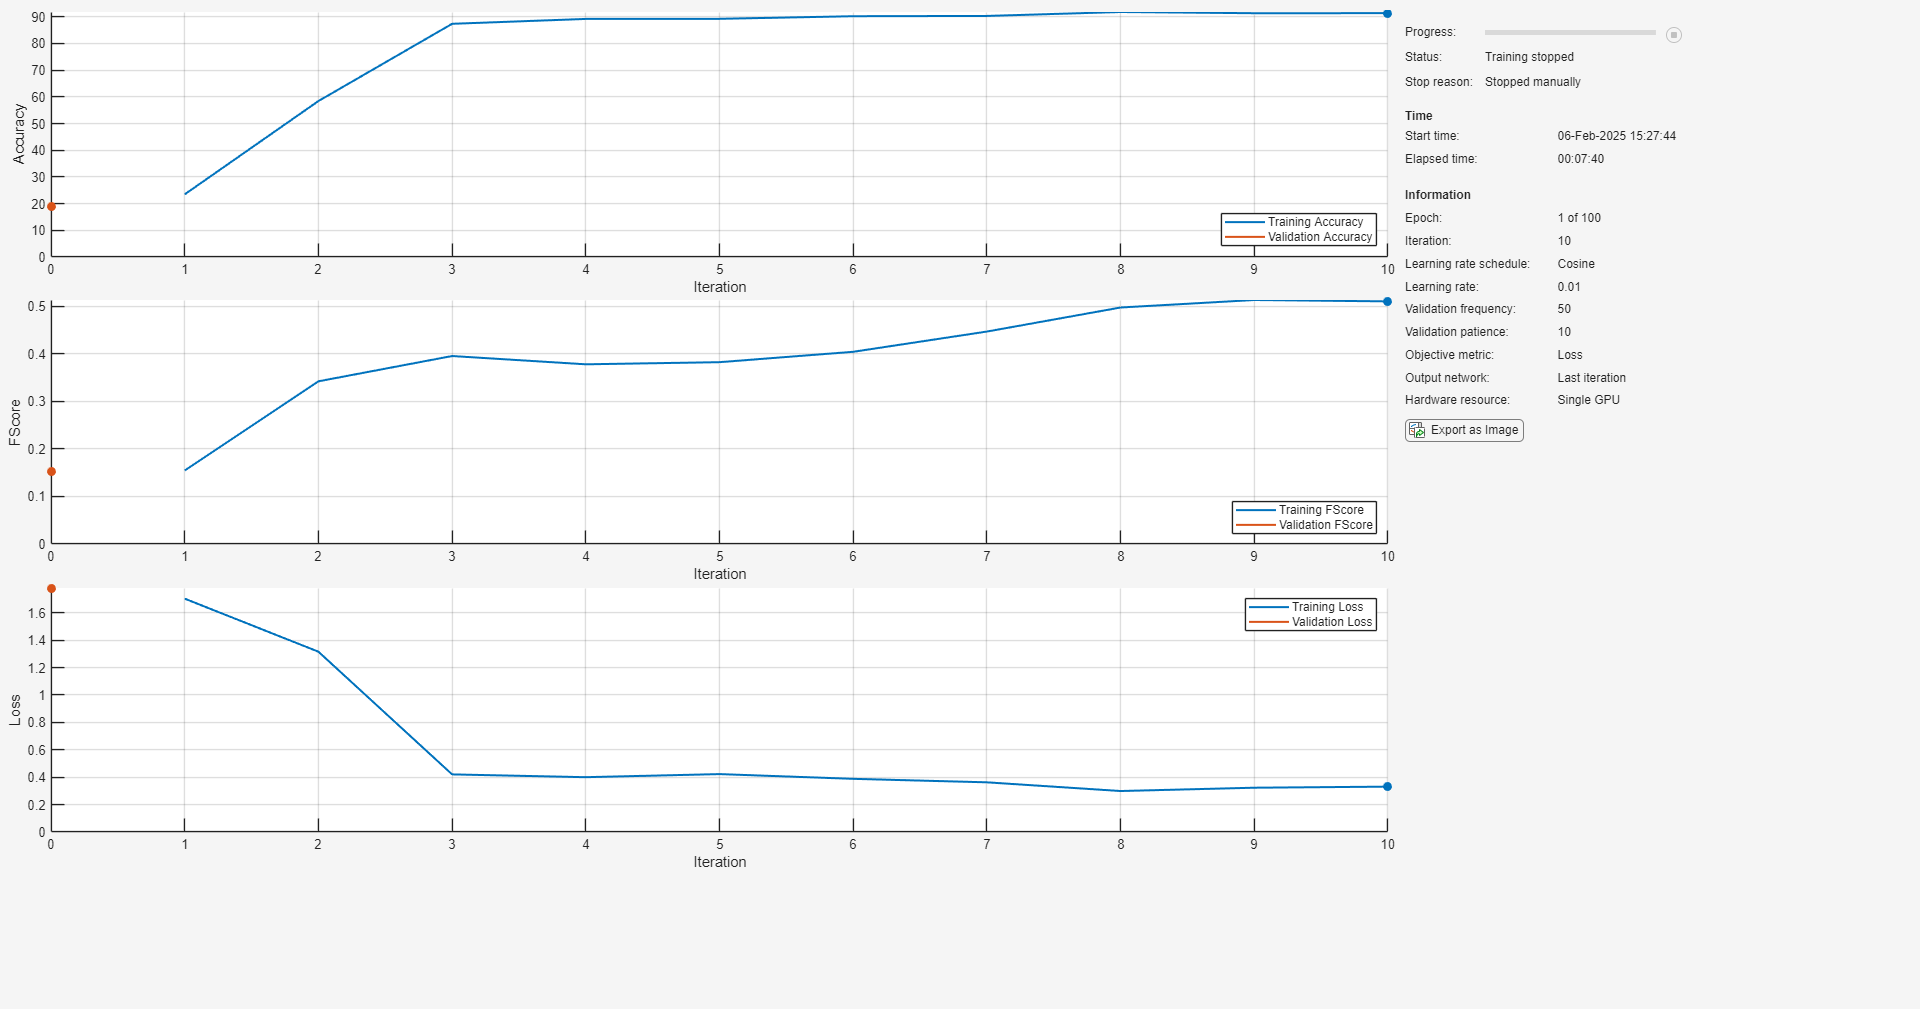

commonHParameters = struct(...
    'numLabels', 3,...
    'numChannels',    numChannels,...
    'dropoutFactor',        0.125,  ...
    'embedDim',                32,...           % also equal to numFilters
    'numHeads',             [2,4], ...          % Number of attention heads
    'numTransformerBlocks', [1,2], ...          % Number of transformer blocks
    'numCNNBlocks',         [1,4],...
    'filterSize',              15 ...    % CNN filter size

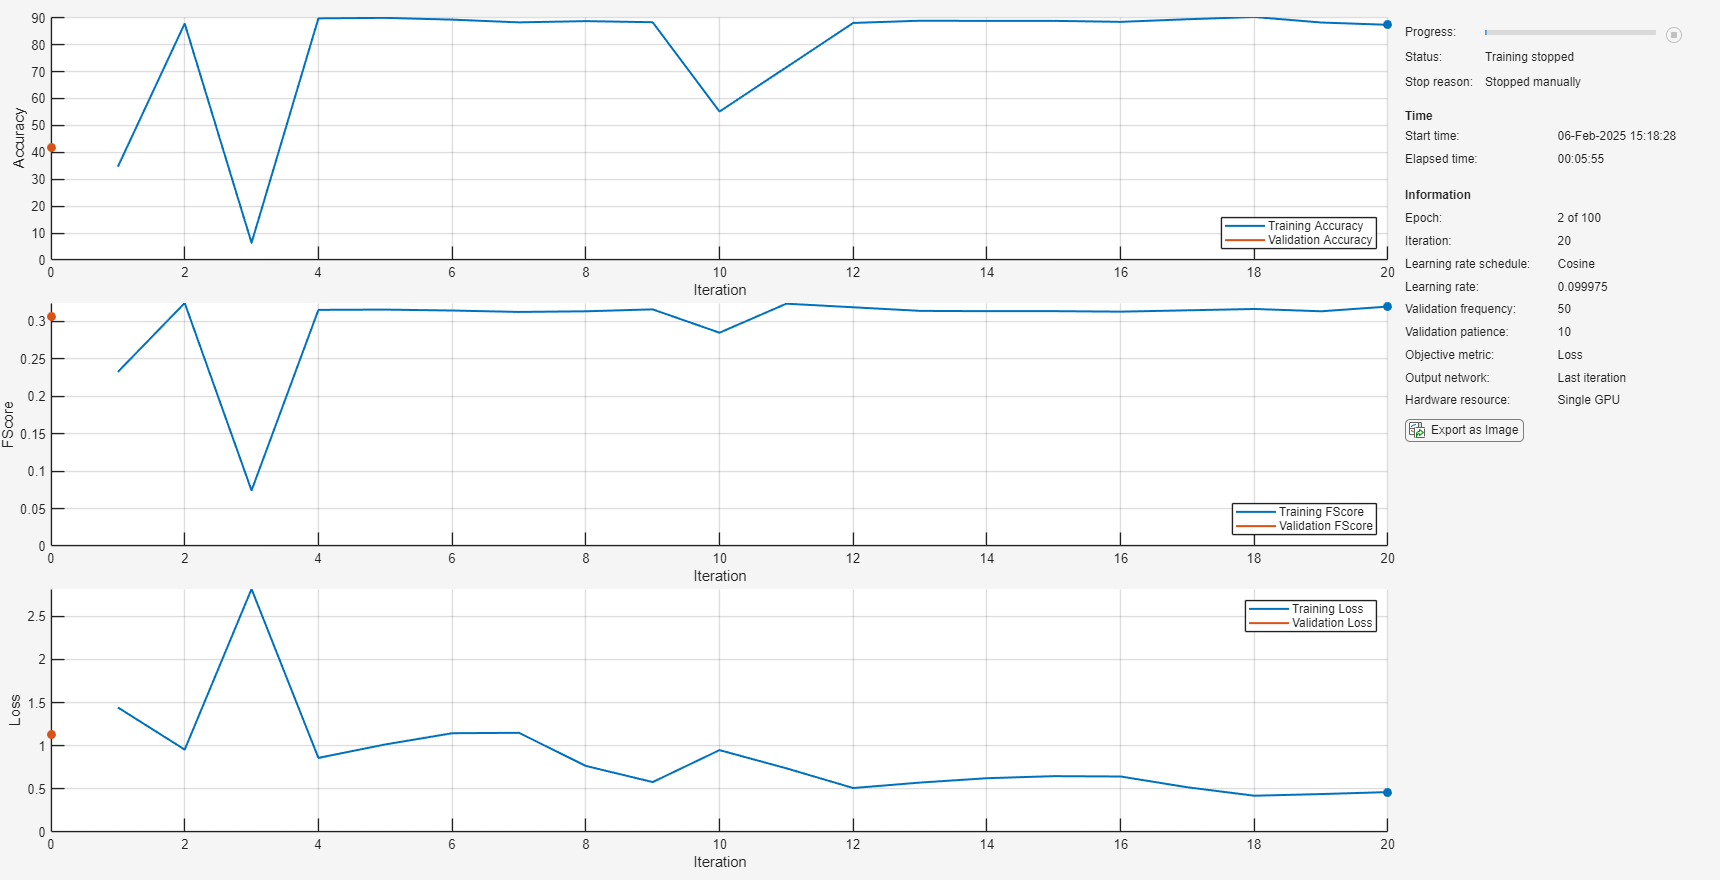

);


% Run grid search
% numTrials = 1;
%options.InitialLearnRate = 1e-2;
options.ExecutionEnvironment = "gpu";
% options.Plots = "training-progress";
% options.Metrics = ["accuracy", "fScore"];
DWCNNTransformerResults = gridSearch(@constructCNNTransformer, XSearchTrainPrepared, YSearchTrainPrepared, XSearchTrainID, ...
                                              XSearchTestPrepared,  YSearchTestPrepared,  XSearchTestID, ...
                                              commonHParameters, options, numTrials, stepLength, ...
                                             ["embedDim", "numHeads", "numTransformerBlocks", "numCNNBlocks"]);

save(fullfile(folderNameToSaveTo, "DWCNNTransformerResults_" + numChannels + ".mat"), 'DWCNNTransformerResults');